# 適応アルゴリズム比較

## 基本

fleng     = 20;     %タップ数
ssize     = 0.05;   %ステップサイズ
fsize     = 200;    %フレームサイズ
NI        = 100;     %イテレータ

plotf = 0;

## LMSフィルタの設計

lmsfilt = dsp.LMSFilter('Length',fleng,'Method','LMS', 'StepSize',ssize);

## NLMSフィルタの設計

nlmsfilt = dsp.LMSFilter('Length',fleng,'Method','Normalized LMS', 'StepSize',ssize);

## APフィルタの設計

po = 5;    %次元数
apfilt = dsp.AffineProjectionFilter('Length',fleng, 'StepSize',0.5 ,'ProjectionOrder', po);

## RLSフィルタの設計

FF = 0.98;  
rlsfilt = dsp.RLSFilter(11, 'ForgettingFactor', FF);

## ノイズの生成

Hp = dsp.ColoredNoise('Color','pink','SamplesPerFrame',fsize);
pinkn = Hp();
if plotf == 1
    plot(pinkn);
end
Hw = dsp.ColoredNoise('Color','white','SamplesPerFrame',fsize);
whiten = Hw();
if plotf == 1
    plot(whiten);
end

firfilt = dsp.FIRFilter('Numerator', fir1(10,[.5, .75]));

sinewave = dsp.SineWave('Frequency',0.01, ...
    'SampleRate',1,'SamplesPerFrame',fsize);

TS1 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','LMS');
TS2 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','NLMS');
TS3 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','AP');
TS4 = dsp.TimeScope('TimeSpan',1.1*fsize*NI,'TimeUnits','Seconds',...
    'YLimits',[-3 3],'BufferLength',4*fsize*NI, ...
    'ShowLegend',true,'ChannelNames', ...
    {'Noisy signal', 'err'},'Title','RLS');

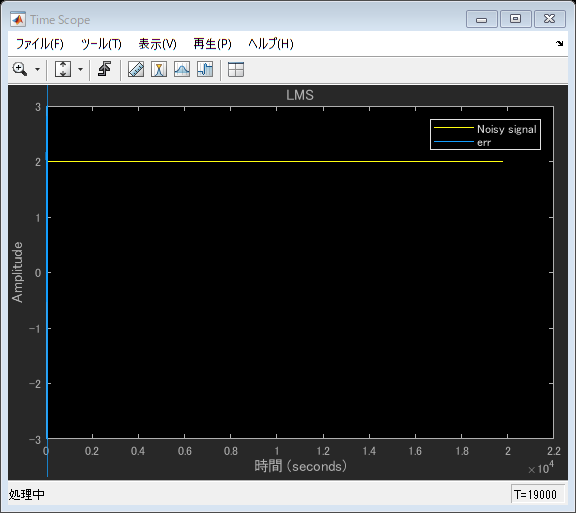

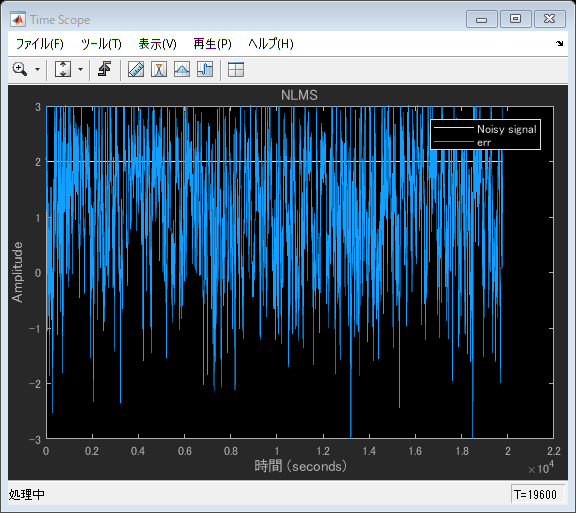

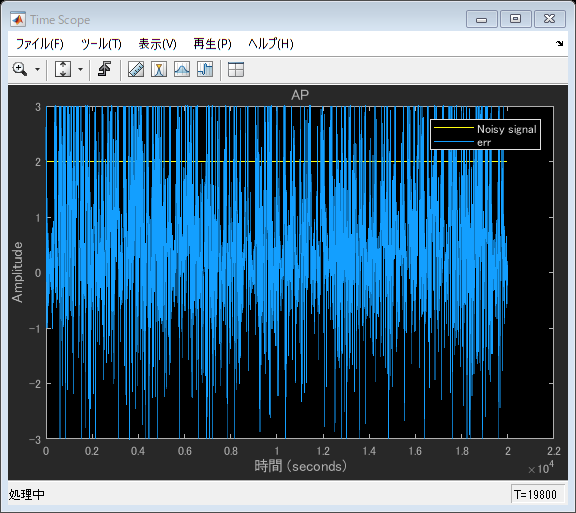

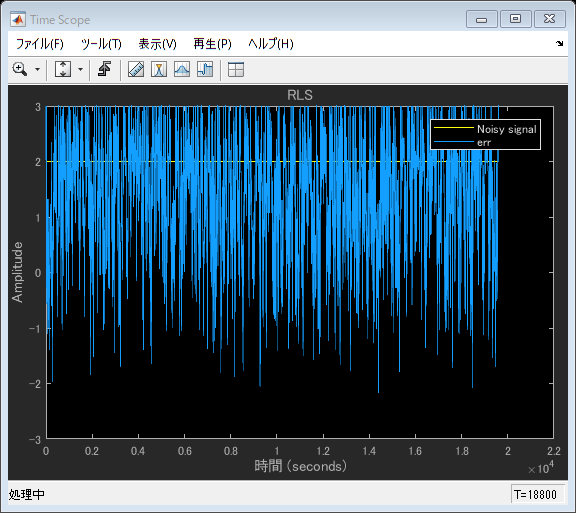

for i = 1:NI
    d = Hp();
    s = ones(fsize,1)*2;
    x = firfilt(d)+s;
    [~,e] = lmsfilt(d,x);
    TS1([s,e]);
    [~,e] = nlmsfilt(d,x);
    TS2([s,e]);
    [~,e] = apfilt(d,x);
    TS3([s,e]);
    [~,e] = rlsfilt(d,x);
    TS4([s,e]);
end